# **Metoda funkcji kary wewnętrznej i zewnętrznej**

**Kara zewnętrzna**

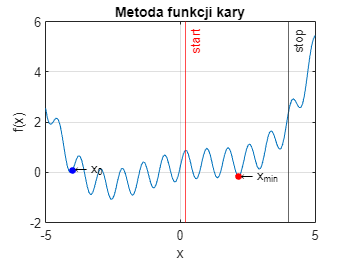

clearvars all; close all;

x = linspace(-5, 5, 150);
f= @(x) 0.2*x+0.6*sin(8*x)+(0.1*x.^2-0.5).^2; 
x0 = -4; 
a = 0.2; 
b = 4; 
c = 0.5;
g1 = @(x) a - x; 
g2 = @(x) x - b;
eps = 1e-3; 

[x_min, i] = external_penalty_method(f, x0, c, g1, g2, eps);

display(f, x, x0, x_min, a, b)

**Kara wewnętrzna**

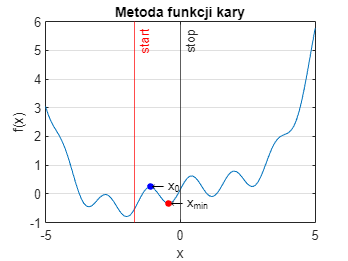

clearvars all; close all;

x = linspace(-5, 5, 100);
f=@(x) 0.2*x+0.4*sin(4*x)+(0.1*x.^2-0.4).^2; 
x0 = -1.123; 
a = -1.7; 
b = 0; 
c = 0.5; 
eps = 1e-3; 
g1 = @(x) a - x; 
g2 = @(x) x - b; 

[x_min, i] = internal_penalty_method(f, x0, c, eps, g1, g2);

display(f, x, x0, x_min, a, b)

function [] = display(f, x, x0, x_min, a, b)
    figure()
    plot(x, f(x)); hold on; grid on;
    plot(x0, f(x0), 'b.', MarkerSize=15)
    plot(x_min, f(x_min), 'r.', MarkerSize=15);
    xline(a, 'r', Label='{start}', HandleVisibility='off')
    xline(b, Label='{stop}', HandleVisibility='off')
    text(x0, f(x0), '\leftarrowx_0');
    text(x_min, f(x_min), '\leftarrowx_{min}')
    xlabel('x'); ylabel('f(x)');
    title("Metoda funkcji kary"); hold off;
end